%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 4.3
% <Demetrios Kechris dkechris@bu.edu>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all; clc;
rng('default')  % For reproducibility of data and results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.3(a)
% Generate and plot the data points
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("4.3a")

4.3a



n1 = 50;
n2 = 100;
mu1 = [1; 2];
mu2 = [3; 2];

% Generate dataset (i) 
disp("i")

i



lambda1 = 1;
lambda2 = 0.25;
theta = 0*pi/6;
[X, Y] = two_2D_Gaussians(n1, n2, mu1, mu2, lambda1, lambda2, theta);

% Scatter plot of the generated dataset
X1 = X(:, Y==1);
X2 = X(:, Y==2);

figure(1);subplot(2,2,1);
scatter(X1(1,:),X1(2,:),'o','fill','b');
grid;axis equal;hold on;
xlabel('x_1');ylabel('x_2');
title(['\theta = ',num2str(0),'\times \pi/6']);
scatter(X2(1,:),X2(2,:),'^','fill','r');
axis equal;

% (ii)
disp("ii")

ii



lambda1 = 1;
lambda2 = 0.25;
theta = 1*pi/6;
[X, Y] = two_2D_Gaussians(n1, n2, mu1, mu2, lambda1, lambda2, theta);

% Scatter plot of the generated dataset
X1 = X(:, Y==1);
X2 = X(:, Y==2);

figure(1);subplot(2,2,2);
scatter(X1(1,:),X1(2,:),'o','fill','b');
grid;axis equal;hold on;
xlabel('x_1');ylabel('x_2');
title(['\theta = ',num2str(1),'\times \pi/6']);
scatter(X2(1,:),X2(2,:),'^','fill','r');
axis equal;

% (iii)
disp("iii")

iii



lambda1 = 1;
lambda2 = 0.25;
theta = 2*pi/6;
[X, Y] = two_2D_Gaussians(n1, n2, mu1, mu2, lambda1, lambda2, theta);

% Scatter plot of the generated dataset
X1 = X(:, Y==1);
X2 = X(:, Y==2);

figure(1);subplot(2,2,3);
scatter(X1(1,:),X1(2,:),'o','fill','b');
grid;axis equal;hold on;
xlabel('x_1');ylabel('x_2');
title(['\theta = ',num2str(2),'\times \pi/6']);
scatter(X2(1,:),X2(2,:),'^','fill','r');
axis equal;

% (iv)
disp("iv")

iv


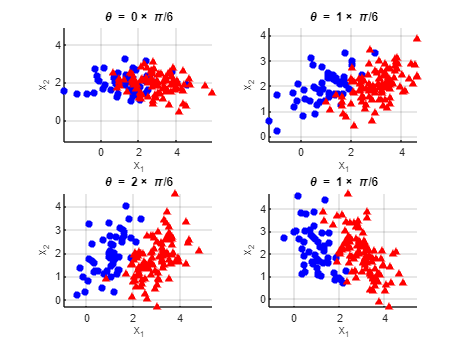


lambda1 = 0.25;
lambda2 = 1;
theta = 1*pi/6;
[X, Y] = two_2D_Gaussians(n1, n2, mu1, mu2, lambda1, lambda2, theta);

% Scatter plot of the generated dataset
X1 = X(:, Y==1);
X2 = X(:, Y==2);

figure(1);subplot(2,2,4);
scatter(X1(1,:),X1(2,:),'o','fill','b');
grid;axis equal;hold on;
xlabel('x_1');ylabel('x_2');
title(['\theta = ',num2str(1),'\times \pi/6']);
scatter(X2(1,:),X2(2,:),'^','fill','r');
axis equal;
hold off;


% Discuss how the eigenvalues and eigenvectors affect the geometry of the dataset:
    % the Eigen values affect the magnitude of the change, larger eigen values will 
    % increase the variance of the points in the distribution.
    % the eigen vectors affect the direction of the change. the angle created
    % by the eigen vectors (which we are setting with Phi) determines the
    % orientation of the line separating the two groups




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.3(b)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("4.3b")

4.3b



% from a(ii)
lambda1 = 1;
lambda2 = 0.25;
theta = 1*pi/6;
[X, Y] = two_2D_Gaussians(n1, n2, mu1, mu2, lambda1, lambda2, theta);

X1 = X(:, Y==1);
X2 = X(:, Y==2);
% For each phi = 0 to pi in steps of pi/48 compute the signal power, noise 
% power, and snr along direction phi and plot them against phi 

phi_array = 0:pi/48:pi;
signal_power_array = zeros(1,length(phi_array));
noise_power_array = zeros(1,length(phi_array));
snr_array = zeros(1,length(phi_array));
for i=1:1:length(phi_array)
    [signal_power, noise_power, snr] = signal_noise_snr(X, Y, phi_array(i), false);
    % See below for function signal_noise_snr which you need to complete.
    signal_power_array(i) = signal_power;
    noise_power_array(i) = noise_power;
    snr_array(i) = snr;
end

signal_power_array;
noise_power_array;
snr_array;

% (i)
% Phi_max (signal) = 2.9452
[M, I_Phi_max_signal] = max(signal_power_array);
Phi_max_signal = phi_array(I_Phi_max_signal)

Phi_max_signal = 2.9452


% (ii)
% Phi_min (noise) = 1.9635
[M, I_Phi_min_noise] = min(noise_power_array);
Phi_min_noise = phi_array(I_Phi_min_noise)

Phi_min_noise = 1.9635


% (iii)
% Phi_max (snr) = 2.4871
[M, I_Phi_max_snr] = max(snr_array);
Phi_max_snr = phi_array(I_Phi_max_snr)

Phi_max_snr = 2.4871

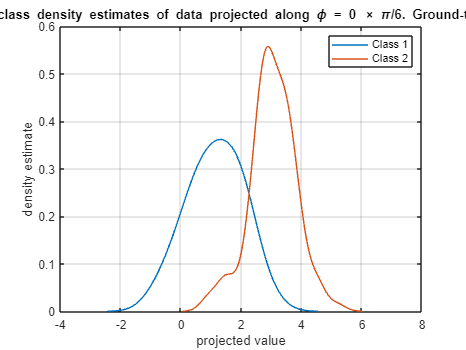


% (iv) for phi0 = 0, phi1 = Pi/6, phi2 = Pi/3
[signal_power0, noise_power0, snr0] = signal_noise_snr(X, Y, 0, true);

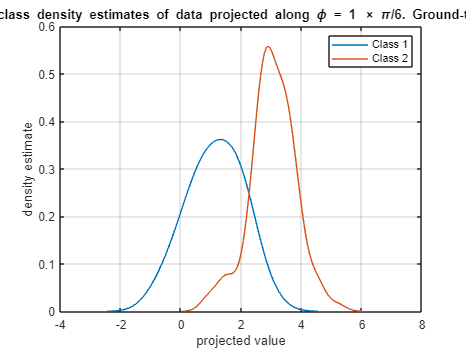

[signal_power1, noise_power1, snr1] = signal_noise_snr(X, Y, pi/6, true);

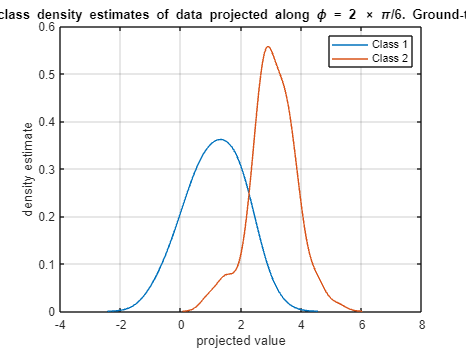

[signal_power2, noise_power2, snr2] = signal_noise_snr(X, Y, pi/3, true);

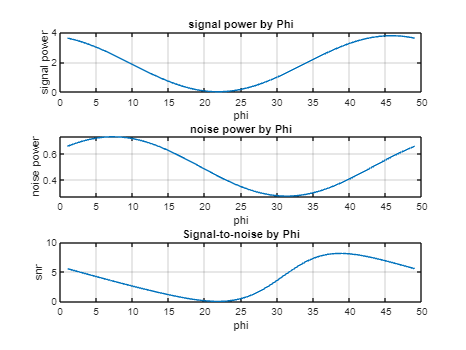



% group of 3 plot for SP NP and SNR
% plot signal_power_array
figure(2);subplot(3,1,1);
plot(signal_power_array);
grid;hold on;
xlabel('phi');ylabel('signal power');
title(['signal power by Phi']);

% plot noise_power_array
figure(2);subplot(3,1,2);
plot(noise_power_array);
grid;hold on;
xlabel('phi');ylabel('noise power');
title(['noise power by Phi']);

% plot snr_array
figure(2);subplot(3,1,3);
plot(snr_array);
grid;hold on;
xlabel('phi');ylabel('snr');
title(['Signal-to-noise by Phi']);



% Discuss your findings
    % Phi_max (signal) = 2.9452
    % Phi_min (noise) = 0.3927
    % Phi_max (snr) = 2.4871
    % The SNR max will be near the max signal and near the minimum noise. 
    % More specifically, it looks close to  halfway between the signal max and the noise 
    % minimum. This is shown by the indeces for max SNR (39) being about halfway between 
    % max signal (46) and min noise (31)



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.3(c)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("4.3c")

4.3c


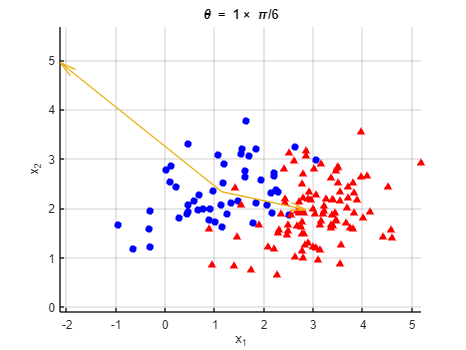


% Compute the LDA solution by writing and invoking a function named LDA 

w_LDA = LDA(X,Y);
meamX1 = XYmean(X1);
meamX2 = XYmean(X2);
diff_muX2_muX1 = meamX2 -meamX1;
figure
scatter(X1(1,:),X1(2,:),'o','fill','b');
grid;axis equal;hold on;
xlabel('x_1');ylabel('x_2');
title(['\theta = ',num2str(1),'\times \pi/6']);
scatter(X2(1,:),X2(2,:),'^','fill','r');
axis equal;
quivx = [meamX1(1,1) meamX1(1,1)];
quivy = [meamX1(2,1) meamX1(2,1)];
u = [w_LDA(1, 1) diff_muX2_muX1(1,1)];
v = [w_LDA(2, 1) diff_muX2_muX1(2,1)];
quiver(quivx, quivy, u, v)
hold off;



% Discuss what you observe. Also compare the direction of wLDA with the value of 
% w_LDA from part (b) which maximizes the SNR.
    % Phi_max(snr) = 2.4871 = phi_array(39)
    % w_LDA = [-3.6365    2.9082]   
    % atan(w_LDA(2)/w_LDA(1)); 
    % ans = -0.6746
    % since w_LDA can be either positive or negative, we add PI
    % atan(w_LDA(2)/w_LDA(1)) + pi;
    % ans = 2.4670
    % phi_array (38)    < w_LDA    < phi_array(39)
    % 2.4216            < 2.4670   < 2.4871
    % 
    % phi(w_LDA) is near the appriximate phi we used to maximize SNR
    % which makes sense since w_LDA is the angle that the produces the largest SNR
    % and phi_array is 48 discrete divisions of pi  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.3(d)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("4.3d")

4.3d



% Create CCR vs b plot

% projecting X onto w_LDA
X_project = w_LDA' * X;

% sorting smallest to highest
X_project_sorted = sort(X_project);

% n = number of data points
n = size(X_project_sorted,2);

% create an array of midpoints where bm is the midpoint between bn and bn+1
% b has 1 x n-1 dimensions
b_array = X_project_sorted * (diag( ones(1,n) ) + diag( ones(1,n-1) ,-1)) / 2;
b_array = b_array(1:(n-1));
ccr_array = zeros(1,n-1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Exercise: decode what the last 6 lines of code are doing and why
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i=1:1:(n-1)
    ccr_array(i) = compute_ccr(X, Y, w_LDA, b_array(i));
end

[Max_CCR, I_blda_max_ccr] = max(ccr_array);
blda_max_ccr = b_array(I_blda_max_ccr)

blda_max_ccr = -0.5842

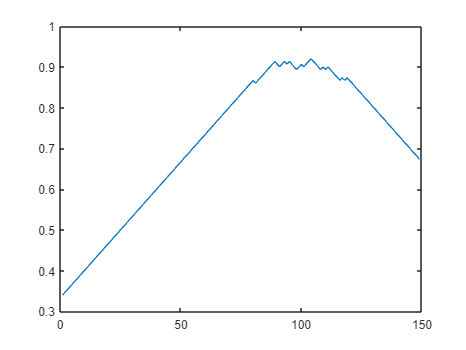


plot(ccr_array)

function [X, Y] = two_2D_Gaussians(n1,n2,mu1,mu2,lambda1,lambda2,theta)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This function should generate a labeled dataset of 2D data points drawn 
% independently from 2 Gaussian distributions with the same covariance 
% matrix but different mean vectors
%
% Inputs:
%
% n1 = number of class 1 examples
% n2 = number of class 2 examples
% mu1 = 2 by 1 class 1 mean vector
% mu2 = 2 by 1 class 2 mean vector
% theta = orientation of eigenvectors of common 2 by 2 covariance matrix shared by both classes
% lambda1 = first eigenvalue of common 2 by 2 covariance matrix shared by both classes
% lambda2 = second eigenvalue of common 2 by 2 covariance matrix shared by both classes
% 
% Outputs:
%
% X = a 2 by (n1 + n2) matrix with first n1 columns containing class 1
% feature vectors and the last n2 columns containing class 2 feature
% vectors
%
% Y = a 1 by (n1 + n2) matrix with the first n1 values equal to 1 and the 
% last n2 values equal to 2

eigenvalues = [lambda1 0;0 lambda2];
u1 = [cos(theta); sin(theta)];
u2 = [sin(theta); -cos(theta)];
u = [u1 u2];
%eu1 = eigenvalues*u12
%eu2 = eigenvalues*u12
eigenmatrix = u*eigenvalues*u';

x1 = mvnrnd(transpose(mu1),eigenmatrix,n1);
x2 = mvnrnd(transpose(mu2),eigenmatrix,n2);

X = [transpose(x1) transpose(x2)];
y1 = 1*ones(1,n1);
y2 = 2*ones(1,n2);
Y = [y1 y2];
end

function [signal, noise, snr] = signal_noise_snr(X, Y, phi, want_class_density_plots)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Insert your code to project data along direction phi and then comput the
% resulting signal power, noise power, and snr 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

w = [cos(phi); sin(phi)];
X1 = X(:, Y==1);
X2 = X(:, Y==2);

meanX1 = XYmean(X1);
meanX2 = XYmean(X2);
Save_cov = ave_cov(X1, X2);

signal = (w'*(meanX2 - meanX1))^2;
noise = w'*Save_cov*w;
snr = signal/noise;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To generate plots of estimated class 1 and class 2 densities of the 
% projections of the feature vectors along direction phi, set:
% want_class_density_plots = true;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    if want_class_density_plots == true
        % Plot density estimates for both classes along chosen direction phi
        datashift_0 = phi_data_shift(X, 0);
        X_projected_phi_class1 = datashift_0(:, Y==1);
        X_projected_phi_class2 = datashift_0(:, Y==2);
        figure();
        [pdf1,z1] = ksdensity(X_projected_phi_class1);
        plot(z1,pdf1)
        hold on;
        [pdf2,z2] = ksdensity(X_projected_phi_class2);
        plot(z2,pdf2)
        grid on;
        hold off;
        legend('Class 1', 'Class 2')
        xlabel('projected value')
        ylabel('density estimate')
        numphi = phi/(pi/6);
        title(['Estimated class density estimates of data projected along \phi = ',num2str(numphi),' \times \pi/6. Ground-truth \phi = \pi/6'])
    end

end

function newdata = phi_data_shift(data1, phi)
w = [cos(phi); sin(phi)];
newdata = w'*data1;
end

function w_LDA = LDA(X, Y)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Insert code to compute and return the LDA solution
% ...
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    X1 = X(:, Y==1);
    X2 = X(:, Y==2);
    w_LDA = calc_wlda(X1, X2);
end

function ccr = compute_ccr(X, Y, w_LDA, b)
    X1 = X(:, Y==1);
    X2 = X(:, Y==2);
    ccr = CCR(X1, X2, w_LDA, b);
end

function mean = XYmean(data)
% takes in an array of data (x1; x2; x3; ...)
% returns the mean of each column
    mean = zeros(size(data,1),1);
    for i = 1:size(data,1)
        Imean = sum(data(i,:))/size(data,2);
        mean(i,1) = Imean;
    end
end

function data_cov = XYcov(data)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dx;d matrix
    mean = XYmean(data);
    data_norm = (data(:, :) - mean);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
end

function ave_cov = ave_cov(data1,data2)
    d1_cov = XYcov(data1);
    d2_cov = XYcov(data2);
    Dtot = [data1 data2];
    ave_cov = (size(data1,2)/size(Dtot,2)*d1_cov) + (size(data2,2)/size(Dtot,2)*d2_cov);
end

function wlda = calc_wlda(data1, data2)
% takes in 2 groups of data
% outputs the best Wlda value associated with them
% Wlda is calculated by using a meshgrid from -10 to 10 in increments of .1
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    Dtot = [data1 data2];
    Dave_cov = ave_cov(data1, data2);
    %to visualize data
    % data_norm1 = (data1(:, :) - mean1)
    % data_norm2 = (data2(:, :) - mean2)
    % scatter(data_norm1(:,1),data_norm1(:,2))
    % hold on
    % scatter(data_norm2(:,1),data_norm2(:,2))
    % hold off
    
    %{
    % use 10x10x.1 meshgrid to find Wlda
    x = -10:.1:10;
    y = -10:.1:10;
    %[X Y] = meshgrid(x,y)
    % size(x,2)
    % size(y,2)
    output = zeros(size(x,2),size(y,2));
    for i = 1:size(x,2)
        for j = 1:size(y,2)
            % output(i,j) = (transpose(w)*(mean2-mean1))^2/(transpose(w)*Dave_cov*w)
            w = [x(1,i); y(1,j)];
            
            % transpose(w);
            % mean2-mean1;
            top = (transpose(w)*(mean2-mean1))^2;
            bot = transpose(w)*Dave_cov*w;
            output(i,j) = top/bot;
        end
    end
    %output
    
    [M,I] = max(output);
    [M2,I2] = max(M);
    yi = I2;
    xi = I(yi);
    %output(xi, yi)
    wlda = [x(xi); y(yi)];
    %}
    
    wlda = inv(Dave_cov) * (mean1-mean2);
end

function CCR = CCR(data1, data2, w, b)
% function takes 2 data sets, w and b
% returns the correct classification rate of the data using +/-w and b
    Dtot = [data1 data2];

    % check CCR for w
    correct = 0;
    for i = 1:size(Dtot,2)
        if (transpose(w)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > size(data1,2)
                correct = correct + 1;
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i <= size(data1,2)
                correct = correct + 1;
            end
        end
    end
    CCRwp = correct / size(Dtot,2);
        
    % check CCR for negative w
    correct = 0;
    w = -w;
    for i = 1:size(Dtot,2)
        if (transpose(w)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > size(data1,2)
                correct = correct + 1;
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i <= size(data1,2)
                correct = correct + 1;
            end
        end
    end
    CCRwn = correct / size(Dtot,2);
    if CCRwp > CCRwn
        CCR = CCRwp;
    else
        CCR = CCRwn;
    end
end